# Asteroid Optical Navigation

ASEN 5044 Final Project Description

*Group Members: *James Monaco, AJ Cuddeback, Grant Kirchoff

## Part 1: Deterministic System Analysis

### 1. Nonlinear Simulation

run('sim_setup.m')
load orbitdetermination-finalproj_data_2023_11_14.mat

% solar radiation pressure 
a_SRP = -Phi_0 / norm(r_S)^2 * (1 + 4/9 * rho) * A_M * r_S / norm(r_S);

% non-linear simualtion
x_0 = [r_0_nom; dr_0_nom];
options = odeset('RelTol',1e-12);
[t_ode45,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), [0 t_f], x_0, options);

% plotting non-linear simulation solution
figure(1);
f = tiledlayout(6,1)

f =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [6 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


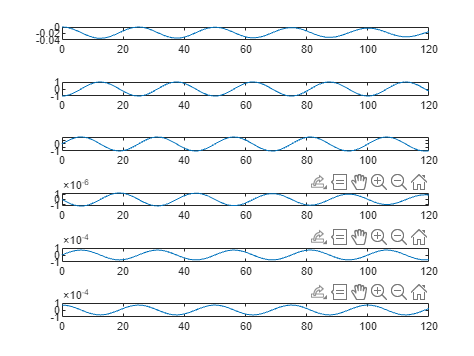

for i = 1:6
    nexttile(f)
    plot(t_ode45/60/60,x_ode45(:,i))
end

### 2. CT Jacobians

Solved by hand

### 3. DT Linarized Model

No code for this? Maybe put DT LTI matrices here?

### 4. Simlation of DT linearized Model

No process noise, no measurement nose, no control input perturbations. Simulation goes here:

Validating against full nonlinear simulation: 

Plotting results: 

## Part 2: Stochastic Nonlienar Filtering

### 5. Linarized KF 

- Use specified nominal state trajectory, control inputs, and covariance matrix

-  Use NEES and NIS $\chi^2
$ test based on MC TMT simulations to tune and validate LKF

### 6. Extended KF 

### 7. Implement LKF and EKF for Estimation

function dx = orbit(~,x_in,a_SRP,mu_A)
    % calculating pertibation forces
    r = x_in(1:3);
    f = a_SRP + a_2B(r,mu_A);
    
    % building the derivative vector
    dx = zeros(size(x_in));
    dx(1:3) = x_in(4:6);
    dx(4:6) = f;
end

function f = a_2B(r,mu_A)
    f = -mu_A / norm(r)^3 * r;
end 